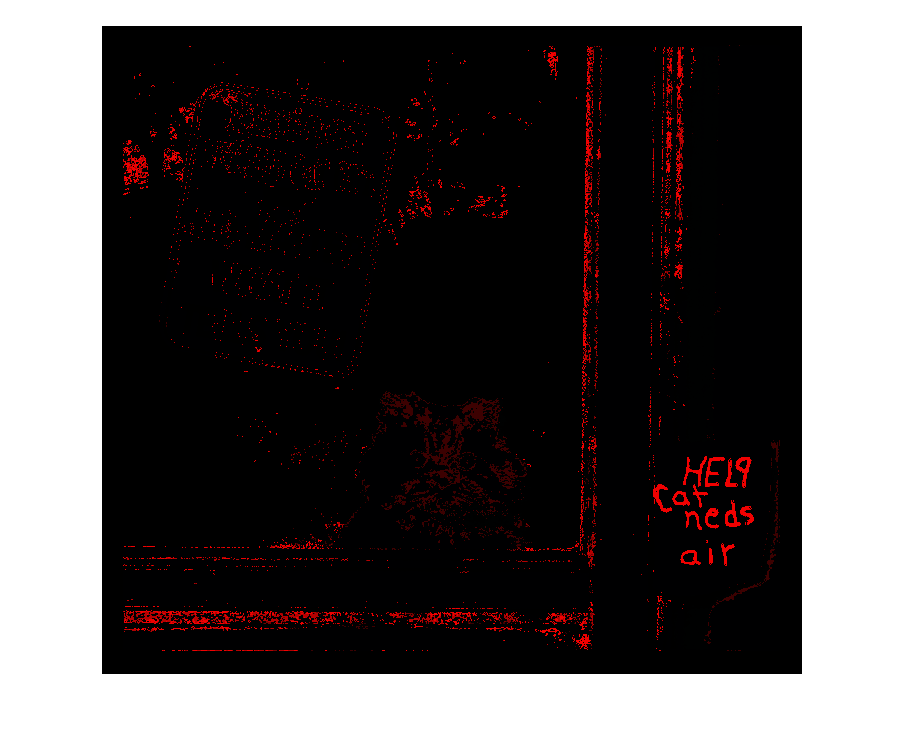

img = imread("Cat.jpg");

% Zielbild preallocation
imgHSV = zeros(size(img), class(img));

[x, y, ~] = size(img);

for row = 1 : x
    for col = 1 : y
        r = img(row, col, 1);
        g = img(row, col, 2);
        b = img(row, col, 3);
        
        maxVal = max([r, g, b]);
        minVal = min([r, g, b]);
        
        sat = (maxVal - minVal) / maxVal;
        
        switch maxVal
            case r
                Hue = (g - b) / (maxVal - minVal);
            case g
                Hue = 2 + ((b - r) / (maxVal - minVal));
            case b
                Hue = 4 + ((r - g) / (maxVal - minVal));
        end
        
        Hue = Hue * 60;
        if Hue < 0
            Hue = Hue + 360;
        end
        
        imgHSV(row, col, 1) = Hue;
        imgHSV(row, col, 2) = sat;
        imgHSV(row, col, 3) = maxVal;
    end
end

imshow(imgHSV)